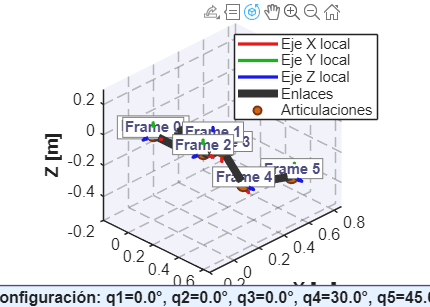

close all; clear all; clc

%% Parámetros de longitud
L1 = 0.2;
L2 = 0.10;
L3 = 0.08;
L4 = 0.2;
L5 = 0.08;
L6 = 0.05;
L7 = 0.05;
L8 = 0.1;
L9 = 0.35;
L10 = 0.4;

%% Configuración inicial (convertir de grados a radianes)
q1 = deg2rad(0);
q2 = deg2rad(0);
q3 = deg2rad(0);
q4 = deg2rad(30);
q5 = deg2rad(45);

%% Función para crear matriz DH estándar
dh_standard = @(theta, d, a, alpha) [
    cos(theta), -sin(theta)*cos(alpha),  sin(theta)*sin(alpha), a*cos(theta);
    sin(theta),  cos(theta)*cos(alpha), -cos(theta)*sin(alpha), a*sin(theta);
    0,           sin(alpha),              cos(alpha),            d;
    0,           0,                       0,                     1
];

%% Transformaciones locales (ahora con T0_w al inicio)
T0_w = [[1 0 0; 0 0 -1; 0 1 0], [0; 0; 0]; 0 0 0 1];
Ta_0 = dh_standard(q1, 0, L1, 0);
Tb_a = [eye(3), [0; L2; 0]; 0 0 0 1];
Tc_b = [eye(3), [0; 0; -L3]; 0 0 0 1];
T1_c = [[0 1 0; 0 0 1; 1 0 0], [L4; 0; 0]; 0 0 0 1];
Td_1 = dh_standard(q2, 0, L5, 0);
T2_d = [[0 0 1; 1 0 0; 0 1 0], [0; 0; -L6]; 0 0 0 1];
Te_2 = dh_standard(q3, 0, L7, 0);
T3_e = [[0 0 1; -1 0 0; 0 -1 0], [0; 0; -L8]; 0 0 0 1];
T4_3 = dh_standard(q4, 0, L9, 0);
T5_4 = dh_standard(q5, 0, L10, 0);

%% Calcular TODAS las transformaciones respecto al frame {w} (world)
Tw_w = eye(4);              % Frame world (origen)
T0_w_world = T0_w;          % Frame 0
Ta_w_world = T0_w_world * Ta_0;      % Frame a
Tb_w_world = Ta_w_world * Tb_a;      % Frame b
Tc_w_world = Tb_w_world * Tc_b;      % Frame c
T1_w_world = Tc_w_world * T1_c;      % Frame 1
Td_w_world = T1_w_world * Td_1;      % Frame d
T2_w_world = Td_w_world * T2_d;      % Frame 2
Te_w_world = T2_w_world * Te_2;      % Frame e
T3_w_world = Te_w_world * T3_e;      % Frame 3
T4_w_world = T3_w_world * T4_3;      % Frame 4
T5_w_world = T4_w_world * T5_4;      % Frame 5

%% Extraer posiciones de TODOS los frames (incluidos w, 0, a, b, c, d, e)
all_frames = {Tw_w, T0_w_world, Ta_w_world, Tb_w_world, Tc_w_world, T1_w_world, ...
              Td_w_world, T2_w_world, Te_w_world, T3_w_world, T4_w_world, T5_w_world};
all_positions = zeros(12, 3);
for i = 1:12
    all_positions(i, :) = all_frames{i}(1:3, 4)';
end

%% Frames numerados para mostrar ejes (w=world, 0,1,2,3,4,5)
numbered_frames = {Tw_w, T0_w_world, T1_w_world, T2_w_world, T3_w_world, T4_w_world, T5_w_world};
numbered_indices = [1, 2, 6, 8, 10, 11, 12]; % Índices en all_frames

%% Crear figura con estilo elegante
fig = figure('Color', 'w', 'Position', [100, 100, 1400, 1000]);
hold on; grid on; axis equal;

% Configurar vista y estilo
view(45, 30);
xlabel('X [m]', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('Y [m]', 'FontSize', 14, 'FontWeight', 'bold');
zlabel('Z [m]', 'FontSize', 14, 'FontWeight', 'bold');
%title('Cadena Cinemática - Visualización 3D (Sistema {w})', 'FontSize', 16, 'FontWeight', 'bold');

% Estilo de grid más elegante
grid on;
set(gca, 'GridAlpha', 0.3, 'GridLineStyle', '--');
set(gca, 'FontSize', 12);

% Color de fondo suave
set(gca, 'Color', [0.95 0.95 0.98]);

%% Dibujar enlaces (links) con grosor - TODOS los segmentos
link_color = [0.2 0.2 0.2]; % Negro oscuro
link_width = 6;

% Dibujar la cadena completa conectando todos los puntos
for i = 1:size(all_positions, 1)-1
    plot3([all_positions(i,1), all_positions(i+1,1)], ...
          [all_positions(i,2), all_positions(i+1,2)], ...
          [all_positions(i,3), all_positions(i+1,3)], ...
          'Color', link_color, 'LineWidth', link_width);
end

%% Dibujar ejes para frames numerados {w}, 0,1,2,3,4,5
axis_length = 0.08;
axis_width = 2.5;

% CONVENCIÓN DE COLORES: R=X, G=Y, B=Z
colors_x = [0.9 0.1 0.1];  % Rojo para X
colors_y = [0.1 0.7 0.1];  % Verde para Y
colors_z = [0.1 0.1 0.9];  % Azul para Z

frame_names = {'Frame {w}', 'Frame 0', 'Frame 1', 'Frame 2', 'Frame 3', 'Frame 4', 'Frame 5'};

for i = 1:7
    T = numbered_frames{i};
    origin = T(1:3, 4);
    x_axis = T(1:3, 1);
    y_axis = T(1:3, 2);
    z_axis = T(1:3, 3);
    
    % Dibujar eje X (ROJO)
    quiver3(origin(1), origin(2), origin(3), ...
            x_axis(1)*axis_length, x_axis(2)*axis_length, x_axis(3)*axis_length, ...
            'Color', colors_x, 'LineWidth', axis_width, 'MaxHeadSize', 1.5, 'AutoScale', 'off');
    
    % Dibujar eje Y (VERDE)
    quiver3(origin(1), origin(2), origin(3), ...
            y_axis(1)*axis_length, y_axis(2)*axis_length, y_axis(3)*axis_length, ...
            'Color', colors_y, 'LineWidth', axis_width, 'MaxHeadSize', 1.5, 'AutoScale', 'off');
    
    % Dibujar eje Z (AZUL)
    quiver3(origin(1), origin(2), origin(3), ...
            z_axis(1)*axis_length, z_axis(2)*axis_length, z_axis(3)*axis_length, ...
            'Color', colors_z, 'LineWidth', axis_width, 'MaxHeadSize', 1.5, 'AutoScale', 'off');
    
    % Etiqueta del frame
    text(origin(1), origin(2), origin(3)+0.05, frame_names{i}, ...
         'FontSize', 11, 'FontWeight', 'bold', 'Color', [0.3 0.3 0.5], ...
         'HorizontalAlignment', 'center', 'BackgroundColor', [1 1 1 0.7], ...
         'EdgeColor', [0.5 0.5 0.5], 'Margin', 1.5);
end

%% Dibujar articulaciones SOLO en frames numerados
joint_color = [0.8 0.4 0.1]; % Naranja
joint_size = 100;

numbered_positions = zeros(7, 3);
for i = 1:7
    numbered_positions(i, :) = all_positions(numbered_indices(i), :);
end

scatter3(numbered_positions(:,1), numbered_positions(:,2), numbered_positions(:,3), ...
         joint_size, 'MarkerFaceColor', joint_color, ...
         'MarkerEdgeColor', [0.5 0.2 0.05], 'LineWidth', 1.5);

%% Añadir leyenda
legend_x = plot3(NaN, NaN, NaN, 'Color', colors_x, 'LineWidth', axis_width);
legend_y = plot3(NaN, NaN, NaN, 'Color', colors_y, 'LineWidth', axis_width);
legend_z = plot3(NaN, NaN, NaN, 'Color', colors_z, 'LineWidth', axis_width);
legend_link = plot3(NaN, NaN, NaN, 'Color', link_color, 'LineWidth', link_width);
legend_joint = scatter3(NaN, NaN, NaN, joint_size, 'MarkerFaceColor', joint_color, ...
                        'MarkerEdgeColor', [0.5 0.2 0.05], 'LineWidth', 1.5);

legend([legend_x, legend_y, legend_z, legend_link, legend_joint], ...
       {'Eje X local', 'Eje Y local', 'Eje Z local', 'Enlaces', 'Articulaciones'}, ...
       'Location', 'northeast', 'FontSize', 11);

%% Información de configuración
config_text = sprintf('Configuración: q1=%.1f°, q2=%.1f°, q3=%.1f°, q4=%.1f°, q5=%.1f°', ...
                      rad2deg(q1), rad2deg(q2), rad2deg(q3), rad2deg(q4), rad2deg(q5));
annotation('textbox', [0.15, 0.02, 0.7, 0.05], 'String', config_text, ...
           'FontSize', 12, 'FontWeight', 'bold', 'HorizontalAlignment', 'center', ...
           'EdgeColor', [0.3 0.3 0.5], 'BackgroundColor', [0.9 0.95 1], ...
           'FitBoxToText', 'on');

%% Ajustar límites de los ejes para mejor visualización
axis_limits = [min(all_positions(:,1))-0.2, max(all_positions(:,1))+0.2, ...
               min(all_positions(:,2))-0.2, max(all_positions(:,2))+0.2, ...
               min(all_positions(:,3))-0.2, max(all_positions(:,3))+0.2];
axis(axis_limits);

% Rotar vista para mejor perspectiva
rotate3d on;

hold off;